# Lezione del 17 Marzo 2021

## Introduzione al linguaggio Matlab

### Assegnazione di variabili

Una variabile in Matlab è creata mediante assegnazione di un valore ad un nome con l'operatore "="

a=10

a = 10

## Matrici e vettori

v1=[1 2 3]

v1 =      1     2     3


m1=[1 2 3 ; 4 5 6]

m1 =      1     2     3
     4     5     6


m2=[1 2 3 ; 4 5 6]'

m2 =      1     4
     2     5
     3     6


zeros(3,2)

ans =      0     0
     0     0
     0     0


eye(3)*2

ans =      2     0     0
     0     2     0
     0     0     2


linspace(1,10,5)

ans =     1.0000    3.2500    5.5000    7.7500   10.0000


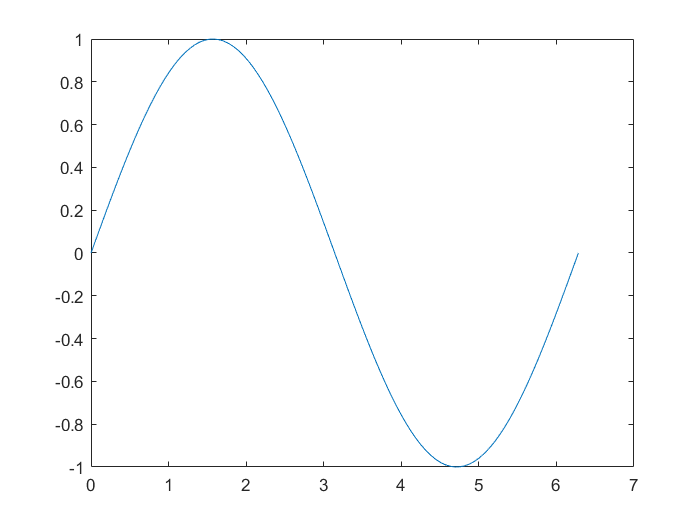

%creo la griglia della ascissa
x=linspace(0,2*pi,100);
plot(x,sin(x)) %genero il grafico di sin(x)

1:5

ans =      1     2     3     4     5


1:0.5:5

ans =     1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000    4.5000    5.0000


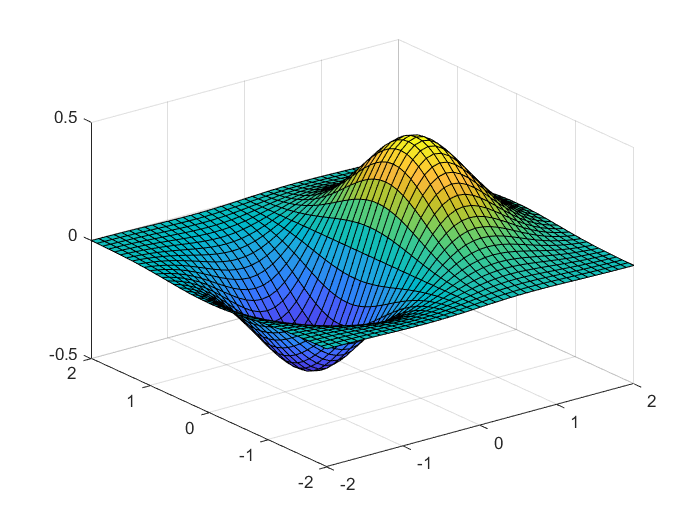

x=-2:0.1:2;
[X,Y]=meshgrid(x);
F=X.*exp(-X.^2 - Y.^2);
surf(X,Y,F);

A=[1 2 3 ; 4 5 6 ];
B=[1 1 1 ; 2 2 2 ];
A.*B

ans =      1     2     3
     8    10    12


### Indici

Elementi o sezioni di matrici e vettori si ottengono mediante indicizzazione:

X(1,2)

ans = -1.9000

X(1:3,10:15)

ans =    -1.1000   -1.0000   -0.9000   -0.8000   -0.7000   -0.6000
   -1.1000   -1.0000   -0.9000   -0.8000   -0.7000   -0.6000
   -1.1000   -1.0000   -0.9000   -0.8000   -0.7000   -0.6000


x(end-3:end)

ans =      6     7     8     9


x=0:9;
odd=(mod(x,2)~=0)%per fare la tilde alt+0126

odd = 1×10 logical array
   0   1   0   1   0   1   0   1   0   1


x(odd)

ans =      1     3     5     7     9


x(~odd)

ans =      0     2     4     6     8


## Operazioni tra vettori/matrici

x*x'

ans = 285

x'*x

ans =      0     0     0     0     0     0     0     0     0     0
     0     1     2     3     4     5     6     7     8     9
     0     2     4     6     8    10    12    14    16    18
     0     3     6     9    12    15    18    21    24    27
     0     4     8    12    16    20    24    28    32    36
     0     5    10    15    20    25    30    35    40    45
     0     6    12    18    24    30    36    42    48    54
     0     7    14    21    28    35    42    49    56    63
     0     8    16    24    32    40    48    56    64    72
     0     9    18    27    36    45    54    63    72    81


x.*x

ans =      0     1     4     9    16    25    36    49    64    81


x(odd) / x(~odd) % soluzione di Ax=B, cioè equivale a B * inv(A)

ans = 1.1667

x(odd) \ x(~odd) % soluzione xA = B

ans =          0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0    0.2222    0.4444    0.6667    0.8889


x(odd) ./ x(~odd) %divisione elemento per elemento

ans =        Inf    1.5000    1.2500    1.1667    1.1250


## Esempio: regressione lineare

Vediamo come calcolare i coefficienti di regressione mediante il metodo matriciale

X=1:10;
y=2 * x + 10 + random("Normal",0,1,1,10)

y =     9.7062   11.1521   12.8799   18.5260   19.6555   20.3075   20.7429   23.1345   25.8235   28.7914


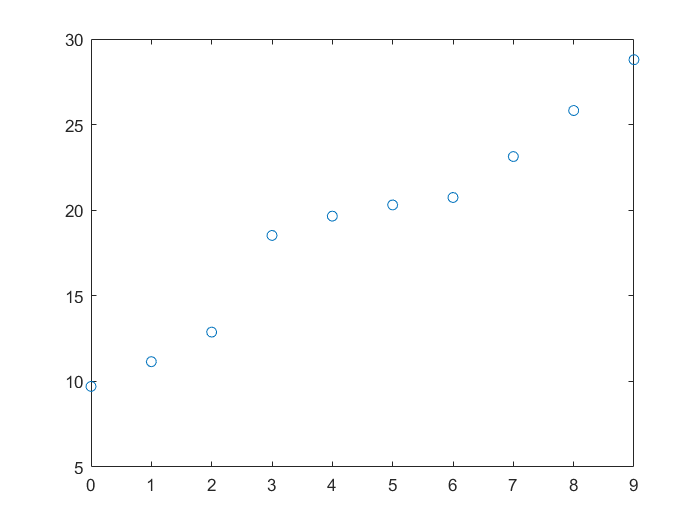

plot(x,y,"o") %la "o" indica che nel plot vengono segnati i punti e basta

A = [x; ones(1,10)]'

A =      0     1
     1     1
     2     1
     3     1
     4     1
     5     1
     6     1
     7     1
     8     1
     9     1


k=inv(A' * A) * A' * y' %formula regressione lineare

k =     2.0184
    9.9890


A\y' %soluzione kA=y

ans =     2.0184
    9.9890


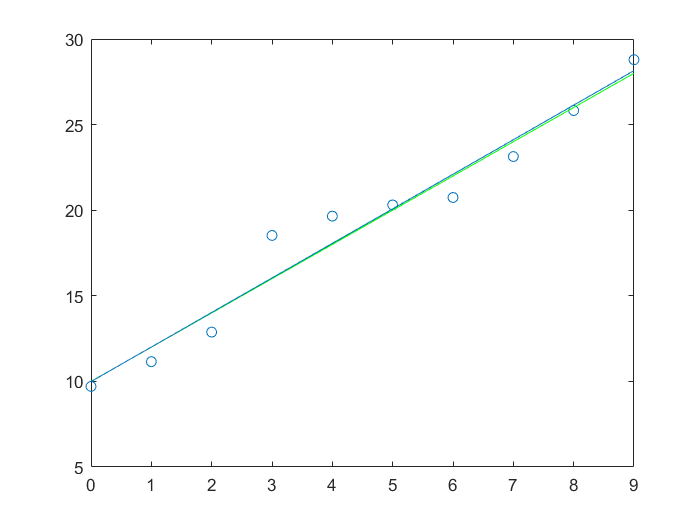

plot(x,y,"o")
hold("on")
plot(x, 2*x +10,"g")
refline(k(1),k(2))
hold("off")

## Cell Array

ca={1,1:10,'one',["one","two","three"]}

ca = 1×4 cell array
    {[1]}    {[1 2 3 4 5 6 7 8 9 10]}    {'one'}    {["one"    "two"    "three"]}


ca(2)

ans = 1×1 cell array
    {[1 2 3 4 5 6 7 8 9 10]}


ca{2} %restituisce l'elemento con il suo formato

ans =      1     2     3     4     5     6     7     8     9    10


ca={1,2,3;'one','two','three'}

ca = 2×3 cell array
    {[  1]}    {[  2]}    {[    3]}
    {'one'}    {'two'}    {'three'}


## Strutture

person.name="Paolo";
person.age=12;
person.height=183;
person %le strutture hanno più campi

person = struct with fields:
      name: "Paolo"
       age: 12
    height: 183


## Structure array

sa = struct('name',{'Pippo','Pluto'},'age',{70,68})

sa = 1×2 struct array with fields:
    name
    age


sa(3).name = "Paperino";
sa(3).age = 65;
sa

sa = 1×3 struct array with fields:
    name
    age


## Tabelle

x = (1:10)';
y=x.^2;
T = table(x,y,'VariableNames', {'X','Y'})

T = 10×2 table
    X      Y 
    __    ___

     1      1
     2      4
     3      9
     4     16
     5     25
     6     36
     7     49
     8     64
     9     81
    10    100


T.X

ans =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


T.Z =T.Y + T.X

T = 10×3 table
    X      Y      Z 
    __    ___    ___

     1      1      2
     2      4      6
     3      9     12
     4     16     20
     5     25     30
     6     36     42
     7     49     56
     8     64     72
     9     81     90
    10    100    110


T.X(3)

ans = 3